# Problem 1

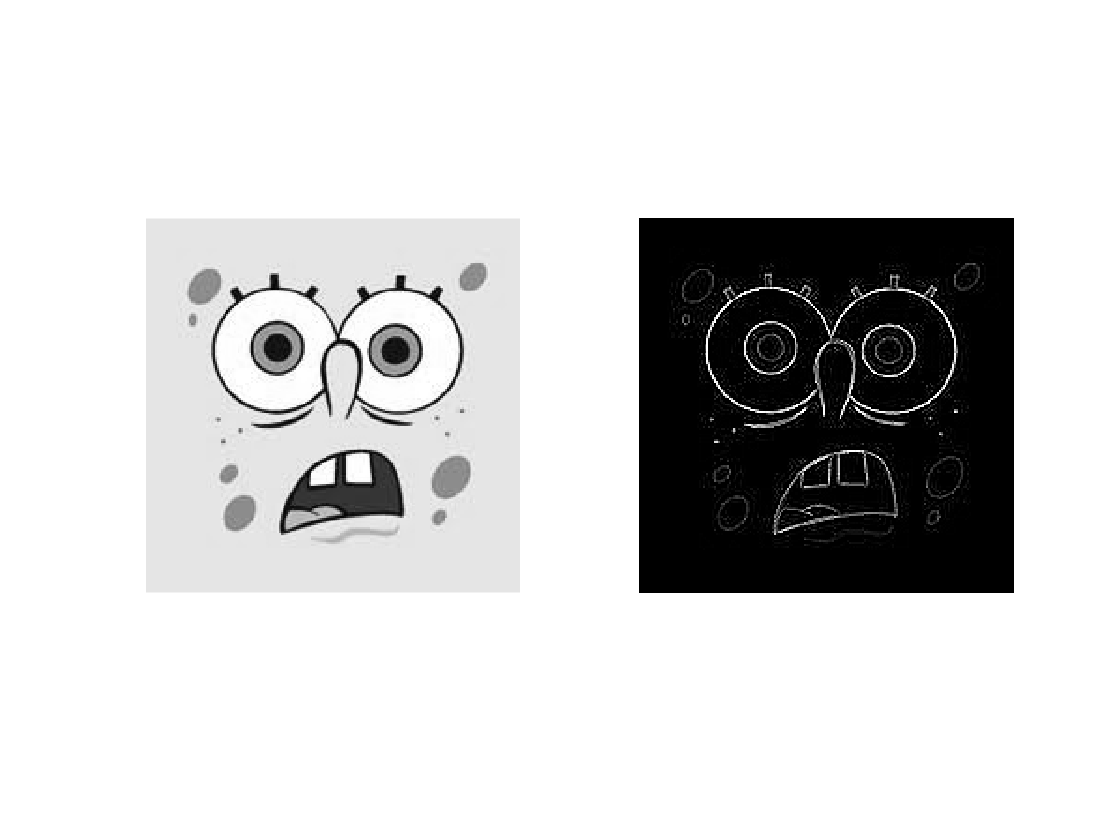

img = imread('Prob1.jpeg');
spongebob = rgb2gray(img);
spongebob = im2double(spongebob);
k1 = [0 1 0; 1 -4 1; 0 1 0];

% (a)
figure(11)
subplot(121); imshow(spongebob);
subplot(122); imshow(conv2(spongebob, k1, 'same'))

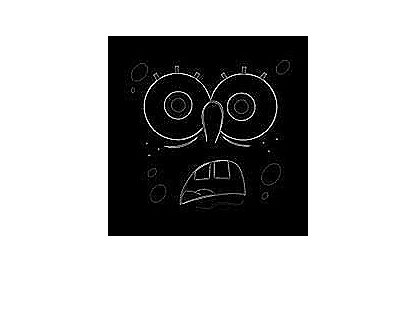


% (b)
[a b]=size(spongebob);
x=zeros([a b]);
for i=2:a-1
    for j=2:b-1
        x(i,j)=sum(sum(spongebob(i-1:i+1, j-1:j+1).*k1));
    end
end

figure(12)
imshow(x);

# Problem 2

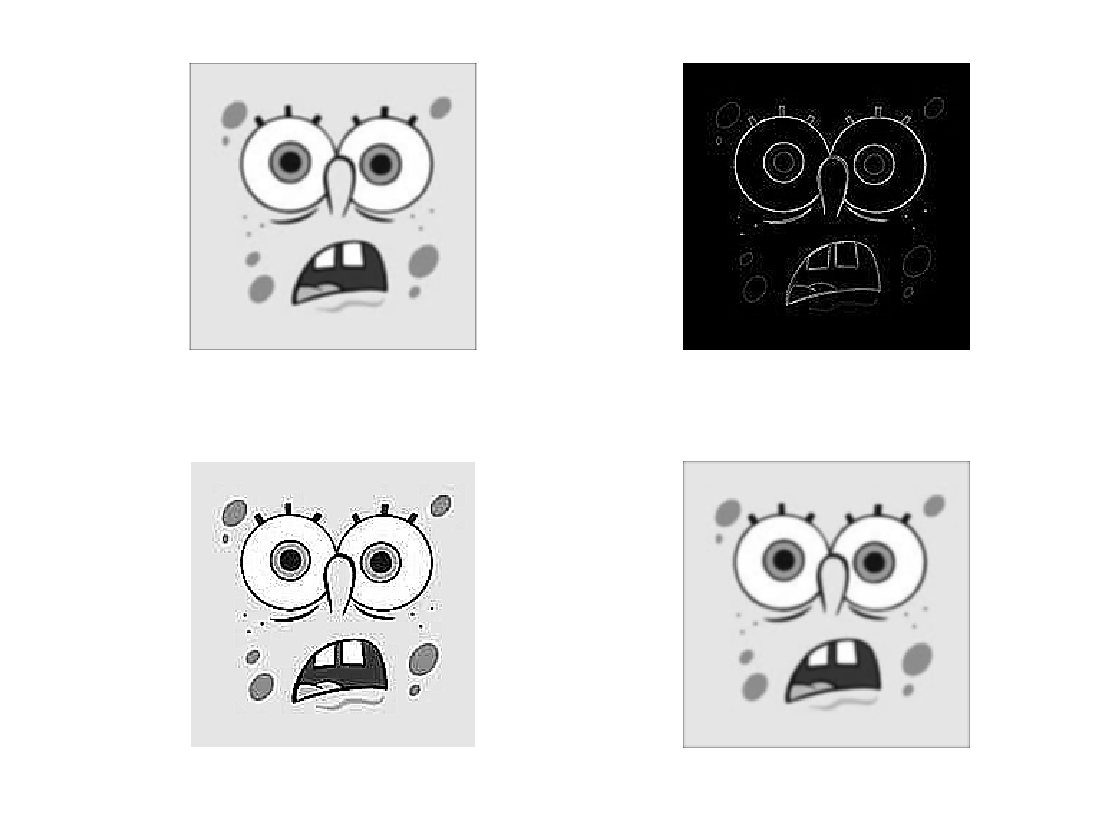

clc; clear all; close all;

img = imread('Prob1.jpeg');
spongebob = rgb2gray(img);
spongebob = im2double(spongebob);

h1 = 1/9*ones(3); 

h2 = [0 1 0; 1 -4 1; 0 1 0];

h3 = [-0.55 -0.55 -0.55; -0.55 5.40 -0.55; -0.55 -0.55 -0.55];

h4 = [0.0030 0.0133 0.0219 0.0133 0.0030;...
    0.0133 0.0596 0.0983 0.0596 0.0133;...
    0.0219 0.0983 0.1621 0.0983 0.0219;...
    0.0133 0.0596 0.0983 0.0596 0.0133;...
    0.0030 0.0133 0.0219 0.0133 0.0030];

figure(1)
subplot(221); imshow(conv2(spongebob, h1, 'same'));
subplot(222); imshow(conv2(spongebob, h2, 'same'));
subplot(223); imshow(conv2(spongebob, h3, 'same'));
subplot(224); imshow(conv2(spongebob, h4, 'same'));

# Problem 3

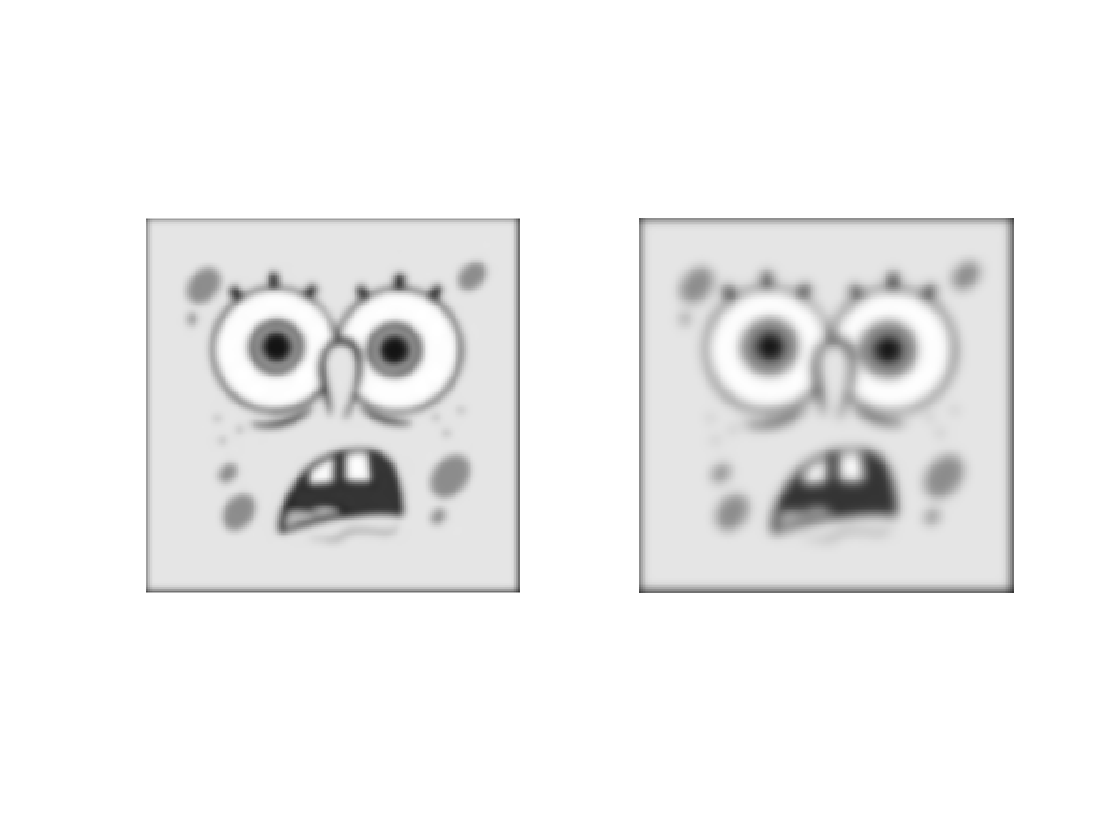

clear; close all; clc;
% (a)
h = fspecial('gaussian',5,2);

numSize = 5;
[x, y] = meshgrid(1:numSize); 
x = x-(round(numSize/2));
y = y-(round(numSize/2));
sigma = 2;

G_sigma = 1/(2*pi*sigma^2)*exp(-(x.^2 + y.^2)/(2*sigma^2));
G_sigma = G_sigma/sum(sum(G_sigma));

% (b)
img = imread('Prob1.jpeg');
spongebob = rgb2gray(img);
spongebob = im2double(spongebob);
h1 = fspecial('gaussian',20,2);
h2 = fspecial('gaussian',20,3);

figure(1)
subplot(121); imshow(conv2(spongebob, h1, 'same'));
subplot(122); imshow(conv2(spongebob, h2, 'same'));

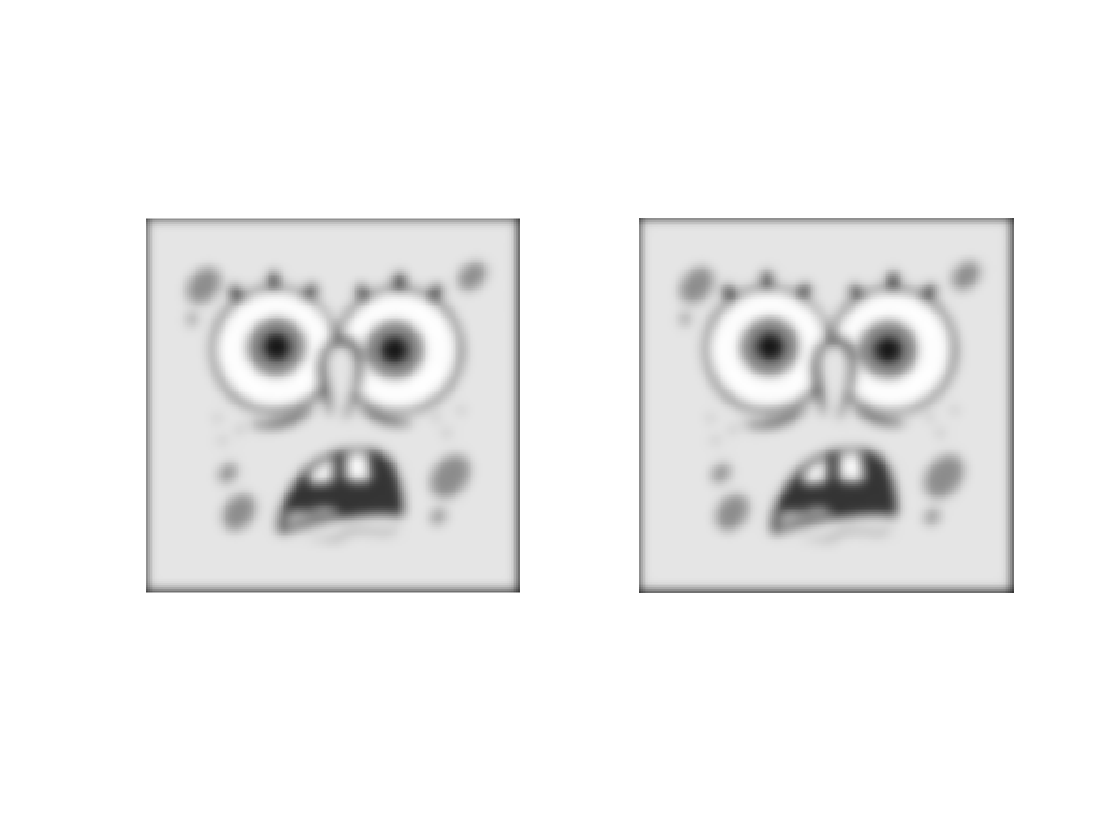


% (c)
h3 = fspecial('gaussian',50,3);

figure(2)
subplot(121); imshow(conv2(spongebob, h2, 'same'));
subplot(122); imshow(conv2(spongebob, h3, 'same'));

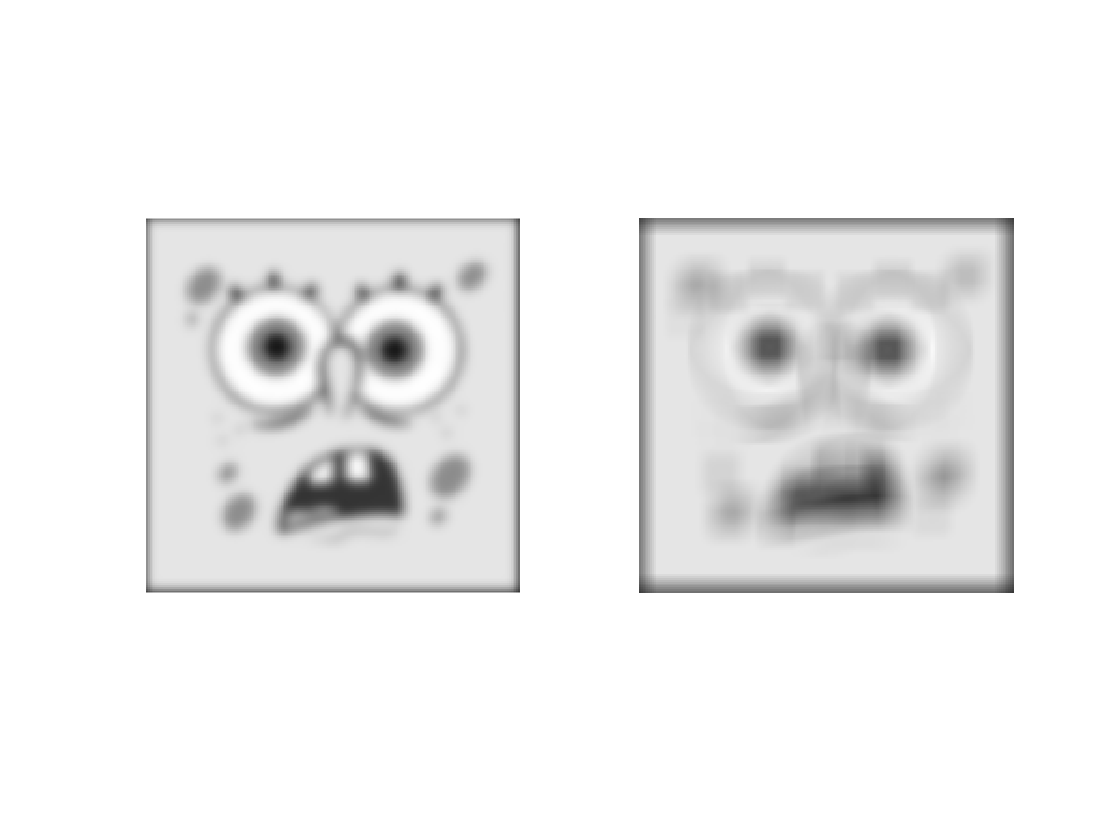


% (d)
h4 = fspecial('gaussian',20,20);

figure(3)
subplot(121); imshow(conv2(spongebob, h2, 'same'));
subplot(122); imshow(conv2(spongebob, h4, 'same'));

# Problem 4

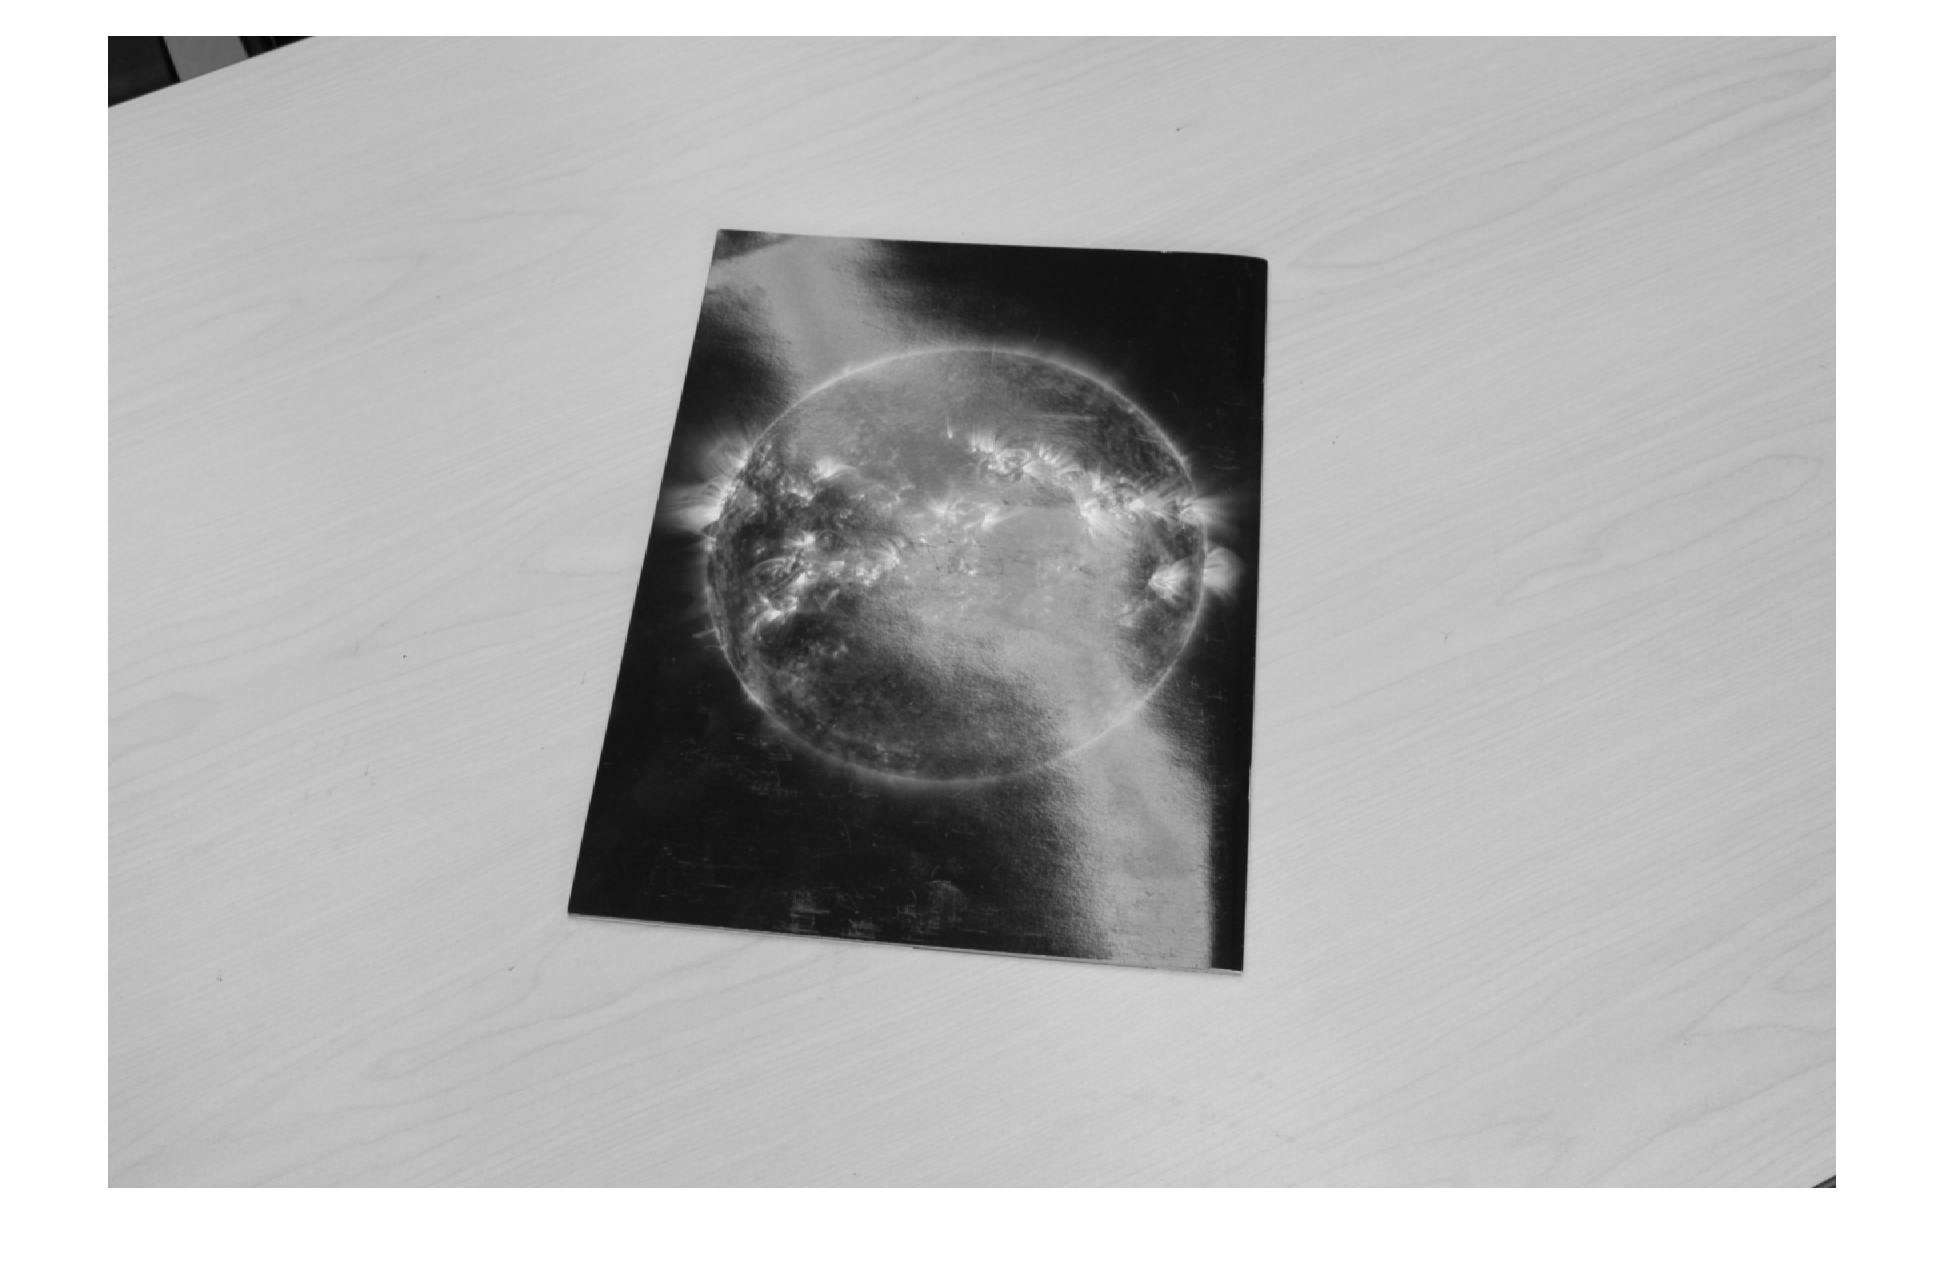

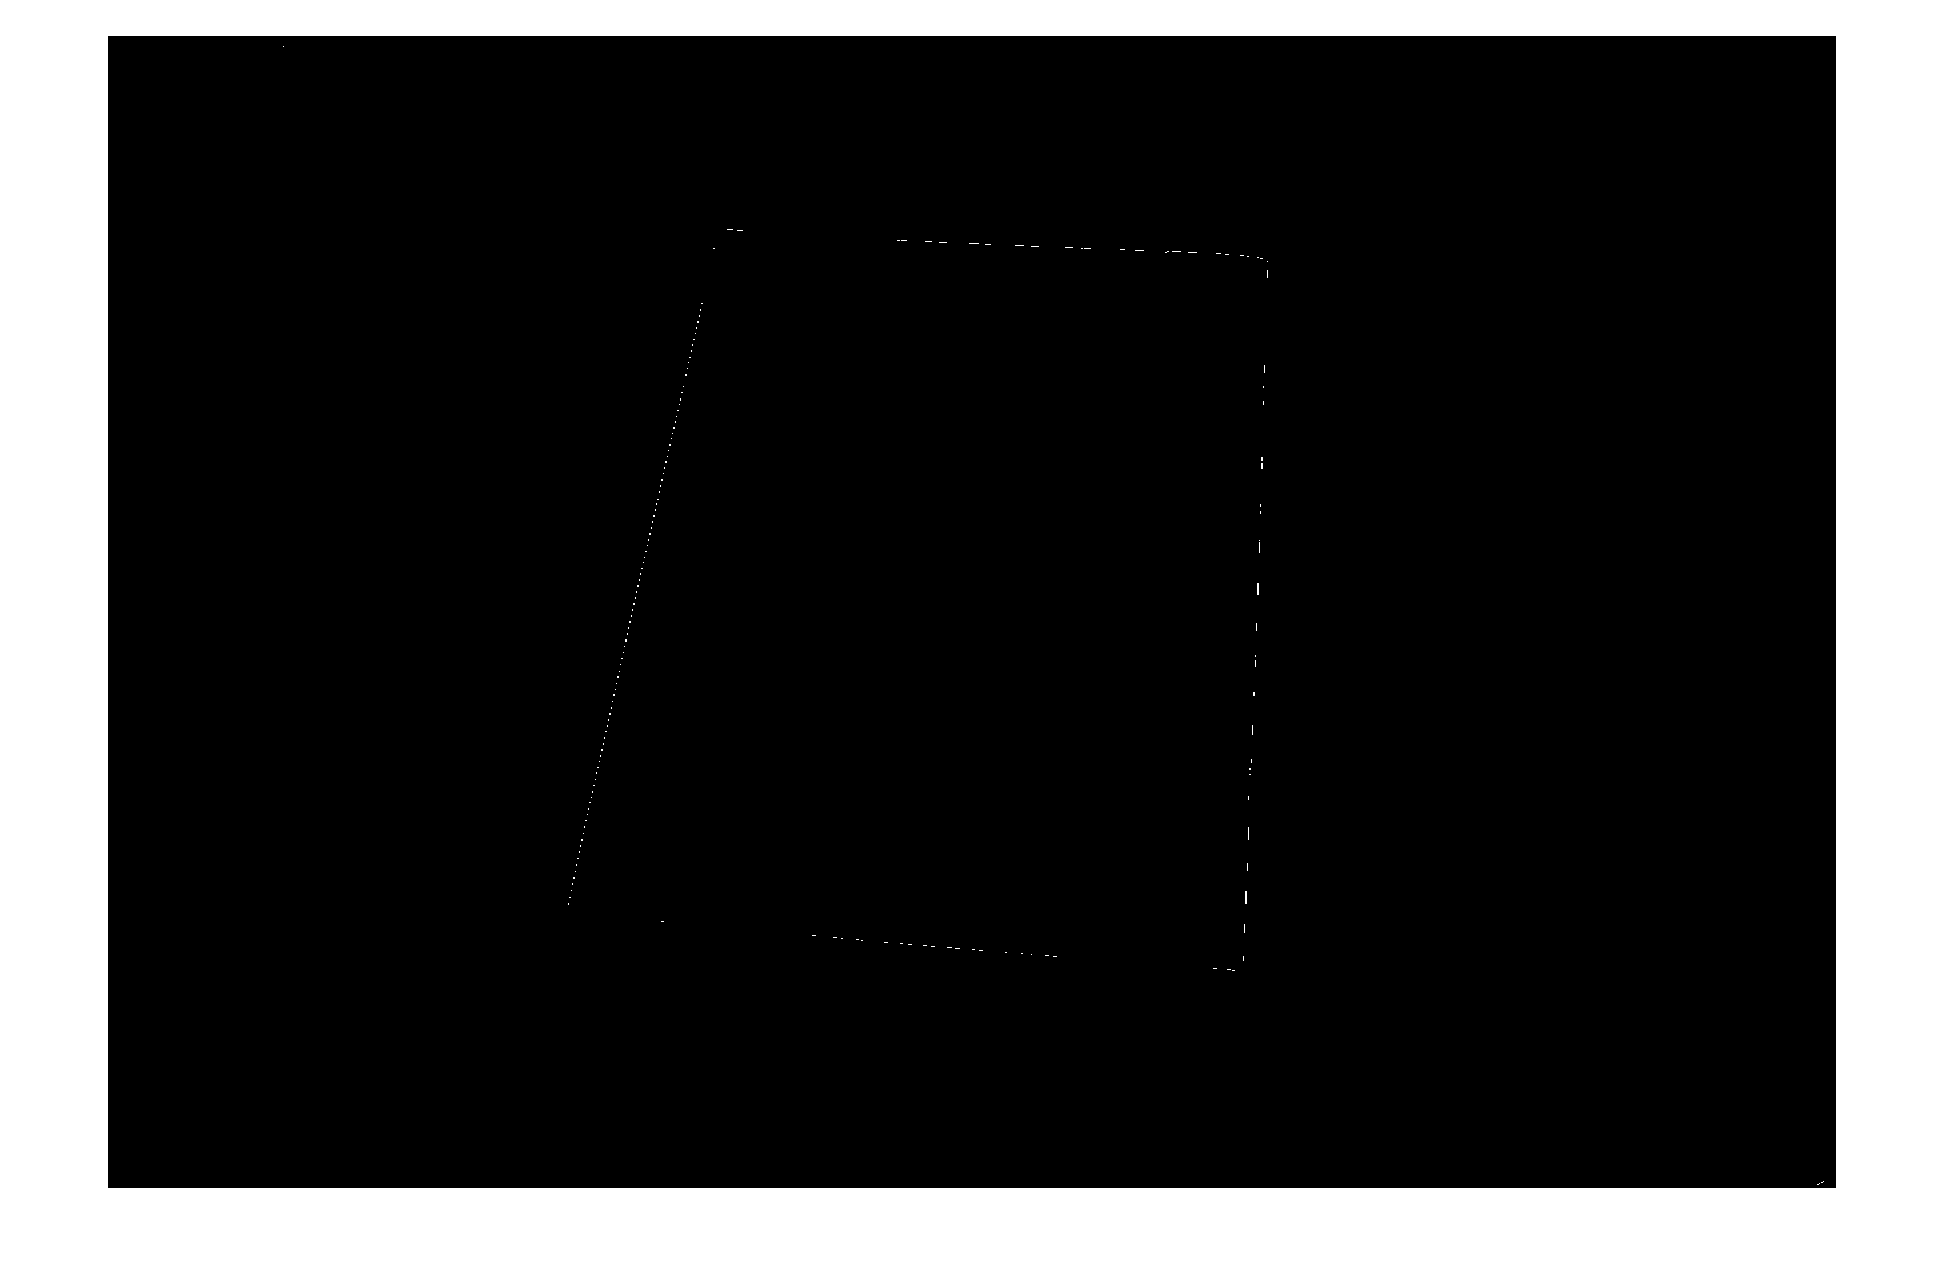

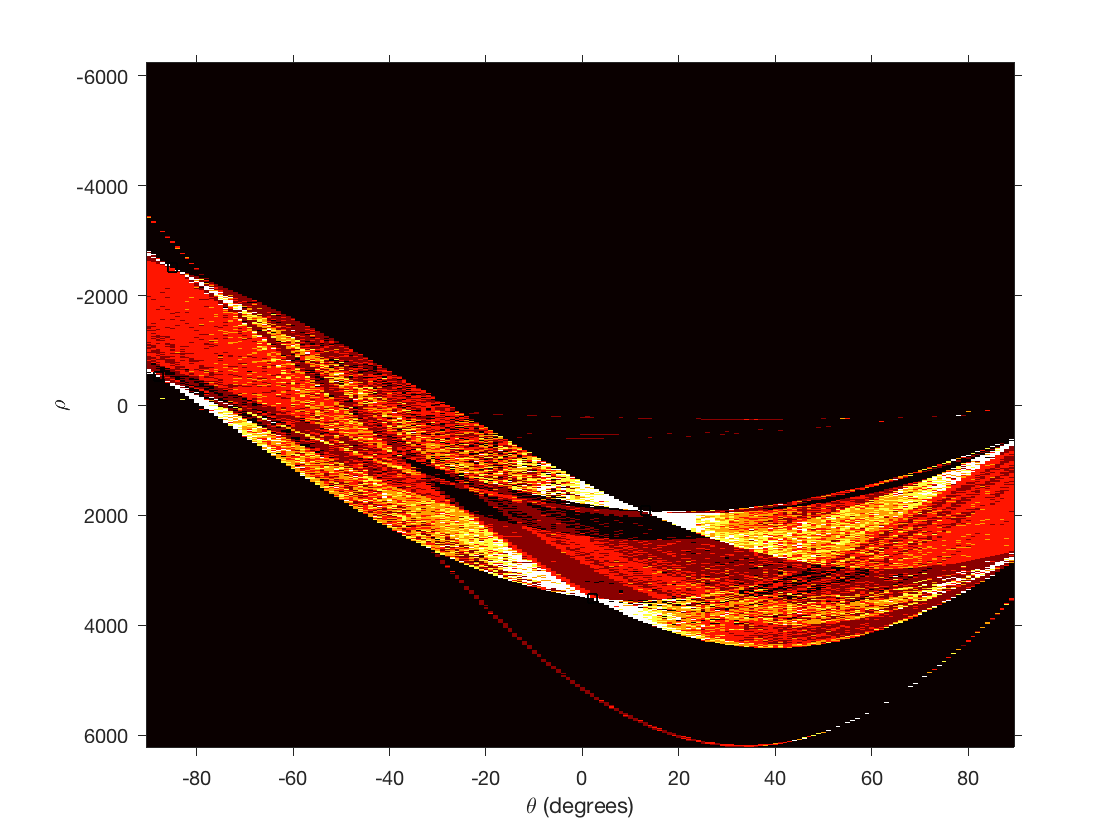

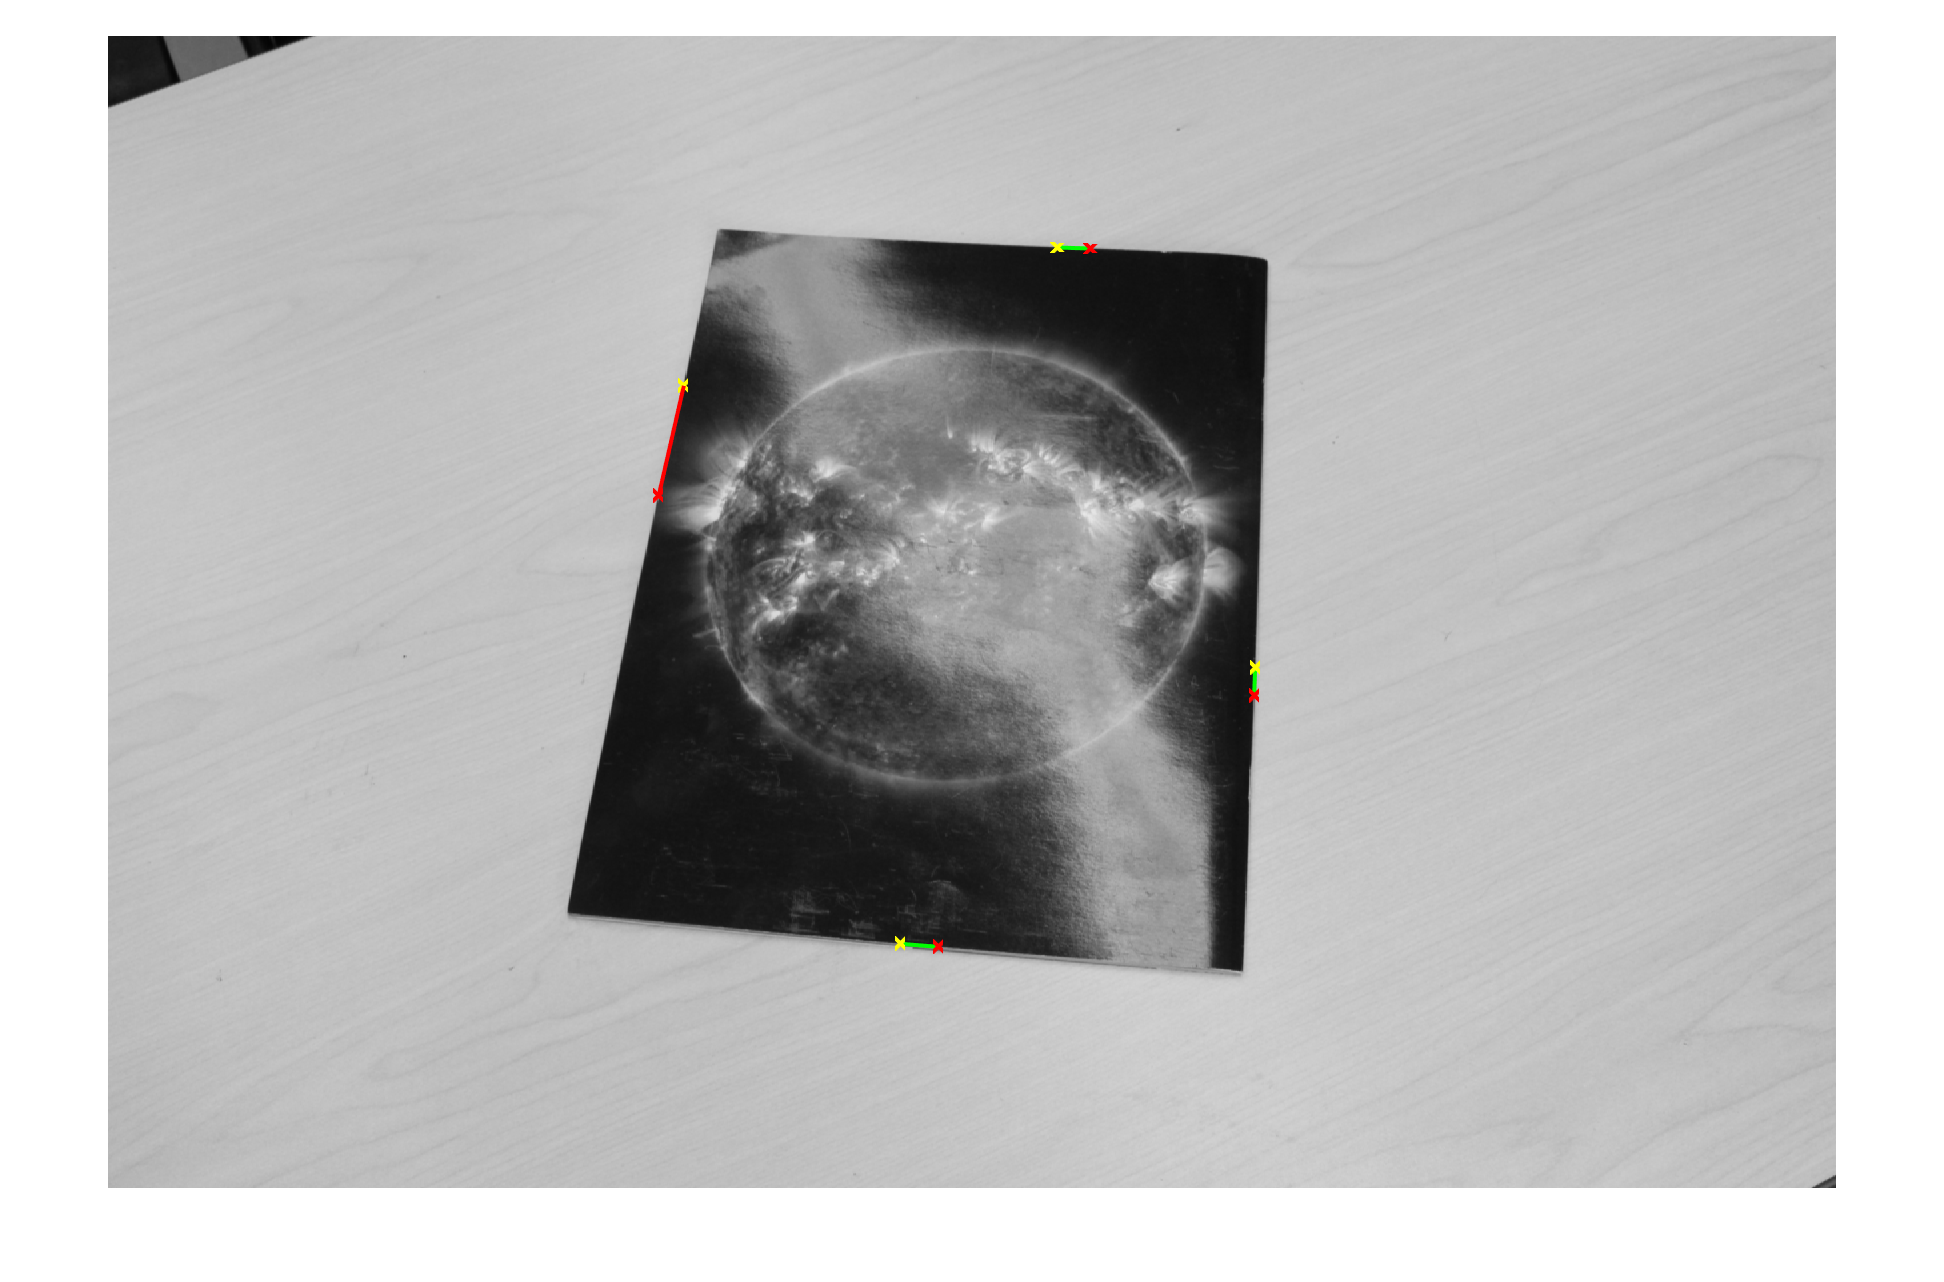

pts =         2848         635        2379        2724        3442        1894        1728        1050
        2947         638        2491        2733        3439        1980        1653        1378


sortedpts = 4×3 table
     xall      yall     sumxy 
    ______    ______    ______

    1829.9    604.15    2434.1
    1363.9    2642.4    4006.3
    3485.2    654.31    4139.6
    3410.2    2806.9      6217


clear; close all; clc; format shortG;

%% Parameter
bookletSize = [24 31.5]; % cm
bookletImgSize = bookletSize*50; % output image size
dirImg = 'img'; % image folder
dirOut = 'out'; % output image folder
imgList = dir('img/*.JPG'); 
nImg = numel(imgList);

%% Processing
for ii=1:nImg
    img = imread(fullfile(dirImg, imgList(ii).name));
    I=rgb2gray(img);
    Iblur = imgaussfilt(I,2);

    BW = edge(Iblur,'sobel',0.08);

    [H1,theta,rho] = hough(BW);
    P = houghpeaks(H1,5,'threshold',ceil(0.3*max(H1(:))));

    x = theta(P(:,2));
    y = rho(P(:,1));

    lines = houghlines(BW,theta,rho,P,'FillGap',5,'MinLength',85);

    T = struct2table(lines); 
    sortedT = sortrows(T, 'theta');
    lines = table2struct(sortedT);

    pts = [lines.point1; lines.point2];
    l1 = cross([pts(1,1),pts(1,2),1]',[pts(2,1),pts(2,2),1]');
    l2 = cross([pts(1,3),pts(1,4),1]',[pts(2,3),pts(2,4),1]');
    l3 = cross([pts(1,5),pts(1,6),1]',[pts(2,5),pts(2,6),1]');
    l4 = cross([pts(1,7),pts(1,8),1]',[pts(2,7),pts(2,8),1]');

    pt1 = cross(l1,l3);
    pt2 = cross(l1,l4);
    pt3 = cross(l2,l3);
    pt4 = cross(l2,l4);

    xall = [pt1(1)/pt1(3) pt2(1)/pt2(3) pt3(1)/pt3(3) pt4(1)/pt4(3)]';
    yall = [pt1(2)/pt1(3) pt2(2)/pt2(3) pt3(2)/pt3(3) pt4(2)/pt4(3)]';
    sumxy = [xall(1)+yall(1) xall(2)+yall(2) xall(3)+yall(3) xall(4)+yall(4)]';

    ptstable = table(xall,yall,sumxy);
    sortedpts = sortrows(ptstable, 'sumxy')
    sortedpts = table2array(sortedpts);

    a1 = sortedpts(1,1);
    a2 = sortedpts(2,1);
    a3 = sortedpts(4,1);
    a4 = sortedpts(3,1);
    b1 = sortedpts(1,2);
    b2 = sortedpts(2,2);
    b3 = sortedpts(4,2);
    b4 = sortedpts(3,2);
 
    x1 = 0;
    x2 = 24;
    x3 = 24;
    x4 = 0;
    y1 = 0;
    y2 = 0;
    y3 = 31.5;
    y4 = 31.5;
    A = sym([x1 y1 1 0 0 0 -x1*a1 -y1*a1 -a1;...
    0 0 0 x1 y1 1 -x1*b1 -y1*b1 -b1;...
    x2 y2 1 0 0 0 -x2*a2 -y2*a2 -a2;...
    0 0 0 x2 y2 1 -x2*b2 -y2*b2 -b2;...
    x3 y3 1 0 0 0 -x3*a3 -y3*a3 -a3;...
    0 0 0 x3 y3 1 -x3*b3 -y3*b3 -b3;...
    x4 y4 1 0 0 0 -x4*a4 -y4*a4 -a4;...
    0 0 0 x4 y4 1 -x4*b4 -y4*b4 -b4]);
 
    HH = null(A);
    HH = double(HH);
    H = [HH(1) HH(2) HH(3);HH(4) HH(5) HH(6);HH(7) HH(8) HH(9)];
    
    [imgTran, RA] = imwarp(img, projective2d(inv(H)));
    bookletImg = imcrop(imgTran, [-RA.XWorldLimits(1), -RA.YWorldLimits(1) bookletImgSize]);
    imwrite(bookletImg, fullfile(dirOut,imgList(ii).name));
end